# Kolokwium zaliczeniowe

### Imię i nazwisko:

### Grupa zajęciowa:

# Część I. Analiza wizualizacji danych (10 punktów)

- Dokonaj analizy poniższego wykresu pod względem wizualnego sposobu przekazu. Wypisz wady (i ewentualnie zalety) przedstawionej wizualizacji danych na tym wykresie. 

- Zaporponuj inny (lepszy) sposób (nie wystarczy podać typu wykresu!), aby można było łatwo odczytać i analizować dane.

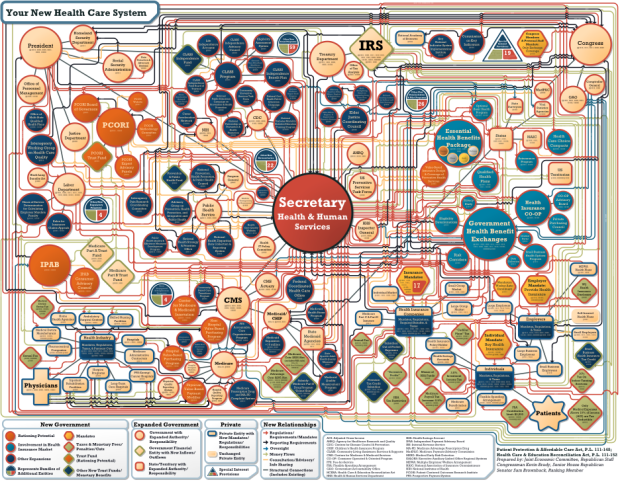

-  Wykres przedstawia zbyt dużą ilość wiadomości przez co jest nieczytelny, linie pokazujące przejście z etapu do etapu przecinają się przez co nie jesteśmy w stanie zrozumiec schematu, jak również litery są zbyt małe przez co są nie do odczytania. Jako zaletę można wymienić kolorystykę gdyż jest kontrastowa oraz każdy element jest obramowany co pozwala na łatwiejsze odróżnienie elementów

- podzielić na kilka wykresów aby dane nie były tak zagęszczone 

# Część II. Matlab (20 punktów)

Zadanie 1. (5 punktów)

Dana jest macierz:

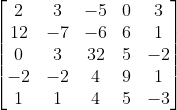

Wyznacz:

a) wartość maksymalną w każdym wierszu, kolumnie, przekątnej oraz całej macierzy. (3 pkt)

b) macierz odwrotną (1 pkt)

c) sumę wszystkich elementów macierzy (1 pkt)

close all
clear 
%a
A = [2 2 -5 0 3; 12 -7 -6 6 1; 0 3 32 5 -2; -2 -2 4 9 1; 1 1 4 5 -3]

A =      2     2    -5     0     3
    12    -7    -6     6     1
     0     3    32     5    -2
    -2    -2     4     9     1
     1     1     4     5    -3


disp('a)')

a)


disp('maxymalna wartość wiersza:')

maxymalna wartość wiersza:


pierwszego = max(A(1,:))

pierwszego = 3

drugiego = max(A(2,:))

drugiego = 12

trzeciego = max(A(3,:))

trzeciego = 32

czwartego = max(A(4,:))

czwartego = 9

piatego = max(A(5,:))

piatego = 5


disp('maxymalna wartość kolumny:')

maxymalna wartość kolumny:


pierwszej = max(A(:,1))

pierwszej = 12

drugiej = max(A(:,2))

drugiej = 3

trzeciej = max(A(:,3))

trzeciej = 32

czwartej = max(A(:,4))

czwartej = 9

piatej = max(A(:,5))

piatej = 3



for i = 1:5
B(i) = [A(i,i)];
C(i) = [A(6-i, i)];
end
disp('maksymalna wartość przekątnej:')

maksymalna wartość przekątnej:


maksymalna = max(B)

maksymalna = 32

maksymalna1 = max(C)

maksymalna1 = 32


disp('maksymalna wartość macierzy:')

maksymalna wartość macierzy:


C = max(A);
maksymalna_m = max(C)

maksymalna_m = 32

disp('b)')

b)


disp('macierz pdwrotna:')

macierz pdwrotna:


odwrotna_A = inv(A)

odwrotna_A =     0.0648    0.0566    0.0248   -0.0749    0.0421
    0.1850   -0.0515    0.0074   -0.0509    0.1460
   -0.0159    0.0055    0.0348   -0.0019   -0.0379
    0.0470   -0.0020   -0.0124    0.0751    0.0796
    0.1403    0.0058    0.0365    0.0806   -0.1885




S1 = 0;
for i = 1:5
    S = sum(A(i,:));
    S1 = S1 + S;

end
disp('sumę wszystkich elementów macierzy')

sumę wszystkich elementów macierzy


Suma = S1

Suma = 64

Zadanie 2. (15 punktów)

Mając dane examgrades.mat

a) wykreśl dane na dowolnym rodzaju wykresu (wykresach). Pamiętaj o pełnym przedstawieniu wykresów zgodnie z zasadami. (10 pkt)

b) wyznacz średnie wartości ocen z poszczgólnych przedmiotów. (2 pkt)

c) jakie były największe oceny z poszczególnych przedmiotów? (3 pkt)

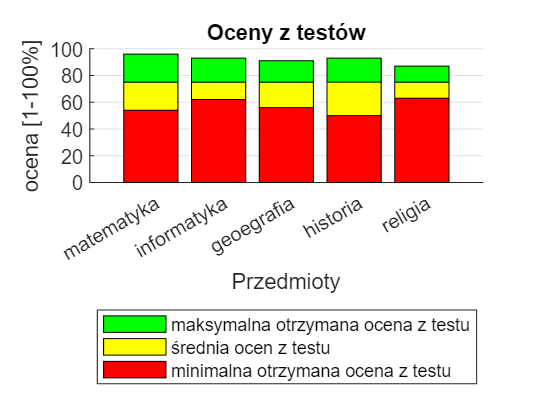

close all
clear
load examgrades.mat

przedmioty = categorical(["matematyka" "informatyka" "geoegrafia" "historia" "religia"]);
przedmioty=reordercats(przedmioty,["matematyka" "informatyka" "geoegrafia" "historia" "religia"]);
maks = max(grades);
min = min(grades);
srednia = mean(grades);

figure 
nexttile
hold on 
bar(przedmioty,maks, 'g')
bar(przedmioty,srednia, 'y')
bar(przedmioty,min, 'r')
hold off


yticks(0:20:100)

xlabel('Przedmioty')
ylabel('ocena [1-100%]')
set(gca,'XGrid','off','YGrid','on')
title('Oceny z testów')
lgd = legend('maksymalna otrzymana ocena z testu', 'średnia ocen z testu', 'minimalna otrzymana ocena z testu');
lgd.Layout.Tile = 'south';


disp('b) wyznacz średnie wartości ocen z poszczgólnych przedmiotów.')

b) wyznacz średnie wartości ocen z poszczgólnych przedmiotów.


srednia

srednia =    75.0083   74.9917   74.9917   75.0333   74.9917


disp('c) jakie były największe oceny z poszczególnych przedmiotów?')

c) jakie były największe oceny z poszczególnych przedmiotów?


maks

maks =     96    93    91    93    87
